close all
clear
clc

## set parameters

current stock price

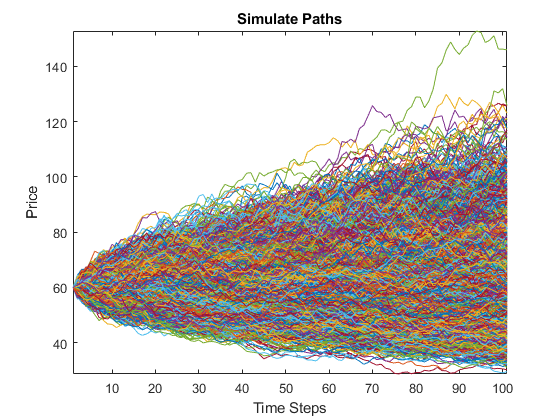

S0 = 60;
% strike price
K = 48;
% risk-free rate
r = 0.06;
% time to maturity
T = 1;
% stock volatility
sigma = 0.2036;
% time steps
nStep = 100;
% path
nPath = 10000;
% simulate stock price
simu = SimulatePath(S0,r,sigma,T,nStep,nPath);
% plot
plot(simu);
axis tight
xlabel('Time Steps');
ylabel('Price');
title('Simulate Paths');

## American call Option

C = LSM(r,K,T,simu);